# LAB 3 - Zakary Steenhoek - MAT 275

# Exercise 1

#### **Read the instructions in your lab pdf file carefully!**

clc; clear;

### **Part (a)**

Define ODE function $f$for your version of the lab.

f = @(t, y) y;

Define vector $t$ of time-values over the interval in your version of the lab, to compute analytical solution vector.

t = linspace(0, 1.8, 100); 
y = 2*exp(t);

Create vector of analytical solution values at corresponding t values.

solns = [t(1:100)', y(1:100)'];

Solve IVP numerically using forward Euler's method with Nsmall timesteps (use variable names as instructed).

Nsmall = 9;
[t9, y9]= euler(f, [0, 1.8], 2, Nsmall); % solve the ODE using Euler w / 9 steps
[t9, y9]

ans =          0    2.0000
    0.2000    2.4000
    0.4000    2.8800
    0.6000    3.4560
    0.8000    4.1472
    1.0000    4.9766
    1.2000    5.9720
    1.4000    7.1664
    1.6000    8.5996
    1.8000   10.3196


Solve IVP numerically using forward Euler's method with Nmed timesteps (use variable names as instructed).

Nmed = 90;
[t90, y90]= euler(f, [0, 1.8], 2, Nmed); % solve the ODE using Euler w / 90 steps
[t90, y90]

ans =          0    2.0000
    0.0200    2.0400
    0.0400    2.0808
    0.0600    2.1224
    0.0800    2.1649
    0.1000    2.2082
    0.1200    2.2523
    0.1400    2.2974
    0.1600    2.3433
    0.1800    2.3902


Solve IVP numerically using forward Euler's method with Nlarge timesteps (use variable names as instructed).

Nlarge = 900;
[t900, y900]= euler(f, [0, 1.8], 2, Nlarge); % solve the ODE using Euler w / 900 steps
[t900, y900]

ans =          0    2.0000
    0.0020    2.0040
    0.0040    2.0080
    0.0060    2.0120
    0.0080    2.0160
    0.0100    2.0201
    0.0120    2.0241
    0.0140    2.0282
    0.0160    2.0322
    0.0180    2.0363


Solve IVP numerically using forward Euler's method with Nhuge timesteps (use variable names as instructed).

Nhuge = 9000;
[t9000, y9000]= euler(f, [0, 1.8], 2, Nhuge); % solve the ODE using Euler w / 9000 steps
[t9000, y9000]

ans =          0    2.0000
    0.0002    2.0004
    0.0004    2.0008
    0.0006    2.0012
    0.0008    2.0016
    0.0010    2.0020
    0.0012    2.0024
    0.0014    2.0028
    0.0016    2.0032
    0.0018    2.0036


In the following steps, we define error as exact - numerical solution value at the last time step

Compute numerical solution error at the last time step for forward Euler with Nsmall timesteps (use variable names as instructed).

eNsmall = y(end)-y9(end)

eNsmall = 1.7797

Compute numerical solution error at the last time step for forward Euler with Nmed timesteps (use variable names as instructed).

eNmed = y(end)-y90(end)

eNmed = 0.2130

Compute numerical solution error at the last time step for forward Euler with Nlarge timesteps (use variable names as instructed).

eNlarge = y(end)-y900(end)

eNlarge = 0.0217

Compute numerical solution error at the last time step for forward Euler with Nhuge timesteps (use variable names as instructed).

eNhuge = y(end)-y9000(end)

eNhuge = 0.0022

Compute ratio of errors between N=Nsmall and N=Nmed. 

ratio1 = eNsmall/eNmed

ratio1 = 8.3544

Compute ratio of errors between N=Nmed and N=Nlarge.

ratio2 = eNmed/eNlarge

ratio2 = 9.8033

Compute ratio of errors between N=Nlarge and N=Nhuge. 

ratio3 = eNlarge/eNhuge

ratio3 = 9.9799

### **FILL OUT THE TABLE BELOW **

Display the table of errors and ratios of consecutive errors for the  numerical solution at `t=tfina`l (the last element in the solution vector).  **REPLACE** words "Nsmall", "Nmed", "Nlarge" and "Nhuge","Nsmall", "yNmed", "yNlarge" and "yNhuge" , "eNsmall",..."ratio1", ... by the appropriate numbers of steps you were given in your version of the lab and by the appropriate values you computed above.  Also, note that in your version of the lab you already have some values entered in the table, to help you check your code is correct. You need to fill out all the cells in the table!

N ={Nsmall; Nmed; Nlarge; Nhuge};
Approximation={y9(end); y90(end); y900(end); y9000(end)};
Error={eNsmall; eNmed; eNlarge; eNhuge};
Ratio ={'N/A'; ratio1; ratio2; ratio3};
table(N,Approximation,Error,Ratio)

ans = 4×4 table
       N        Approximation      Error         Ratio   
    ________    _____________    __________    __________

    {[   9]}     {[10.3196]}     {[1.7797]}    {'N/A'   }
    {[  90]}     {[11.8863]}     {[0.2130]}    {[8.3544]}
    {[ 900]}     {[12.0776]}     {[0.0217]}    {[9.8033]}
    {[9000]}     {[12.0971]}     {[0.0022]}    {[9.9799]}


### **Part (b)**

The continous error rate in the Euler's method relates to the number of steps used as the error decreases by a factor of ~10 each time the steps are increased by a factor of 10. this means that, for every extra step the Uler's method equation uses, the error between the analytical answer and the Euler's approximation gets smaller by a factor of k^1=k, in other words, the error is reduced by a factor of k^1.

### **Part (c)**

The geometric interpretation of Eulers mothod is based on the contruction of tangent lines that are used to approximate the solution to the ODE. Euler's approximations underestimate this particular solution because the shape of the graph that we are analyzing is concave up, therefore when stepping away from the tangent line at any point Po to point, P the approximation at P will be less than the real value at point P.

# Exercise 2

**Read the instructions in your lab pdf file carefully!**

### Part (a)

Plot slopefield for the new ODE  using the given commands. 

t = 0:0.5:8; y = -11:1.8:7; % define a grid in t & y directions
[T, Y] = meshgrid(t, y); % create 2 d matrices of points in ty - plane
dT = ones(size(T)); % dt =1 for all points
dY = -1.6*Y; % dy = -1.6* y ; this is the ODE
quiver (T, Y, dT, dY) % draw arrows (t , y ) - >( t + dt , t + dy )
axis tight % adjust look
hold on 

### Part (b)

Define vector t of time-values over the  given interval  to define analytical solution vector.

t_exact = linspace(0,8,100);

Create vector of analytical solution values at corresponding t values.

y_exact = exp(-1.6*t_exact);

Plot analytical solution vector with slopefield from (a). 

plot(t_exact, y_exact, 'k', 'linewidth', 2)

### Part (c)

Define ODE function.

funcODE = @(t, y) -1.6*y;

Compute numerical solution to IVP with N timesteps using forward Euler.

N=5;
[t_approximate, y_approximate] = euler(funcODE, [0,8], 1, N);

Plot numerical solution with analytical solution from (b) and slopefield from (a) using circles to distinguish between the approximated data (i.e., the numerical solution values) and actual (analytical) solution.

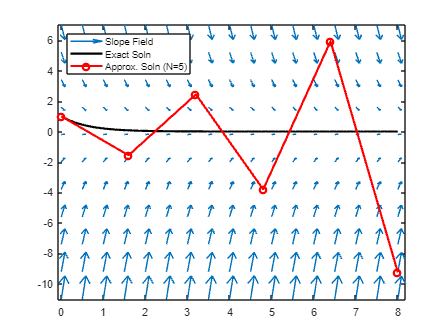

plot(t_approximate, y_approximate, 'ro-', 'linewidth', 2)
legend('Slope Field', 'Exact Soln', 'Approx. Soln (N=5)', 'location', 'northwest')
hold off;   %end plotting in this figure window

**Your response to the essay question for part (c) goes here. **

Eulers method appromiates the soltuion of a differential equation by taking small steps away from a point along the tangent line to the solution at that point. The accuracy depends both on number of steps and the size of the interval. The number of steps used here is very small and the interval that we are analyzing Euler's solution to is also relativley large. We have N=5 steps over interval [0,8] which provides an estimate at points for N=0:5; 1.6N. This gives us a quite inaccurate estimates over the interval we are analyzing since the method is getting more and more inaccurate, as it is overcorrecting for its own error.

### Part (d)

 Define new grid of t and y values at which to plot vectors for slope field.

figure
t = 0:0.5:8; y = -0.6:0.2:1.3;

Plot slope field  corresponding to the new grid.

[T, Y] = meshgrid(t, y); % create 2 d matrices of points in ty - plane
dT = ones(size(T)); % dt =1 for all points
dY = -1.6*Y; % dy = -1.6* y ; this is the ODE
quiver (T, Y, dT, dY) % draw arrows (t , y ) - >( t + dt , t + dy )
axis tight % adjust look
hold on

Define vector t of time-values over the given interval to define analytical soution vector.

t_exact = linspace(0,8,100);

Create vector of analytical solution values at corresponding t values.

y_exact = exp(-1.6*t_exact);

Plot analytical solution vector with new slopefield.

plot(t_exact, y_exact, 'k', 'linewidth', 2)

Define ODE function.

funcODE = @(t, y) -1.6*y;

Compute numerical solution to IVP with the given timesteps using forward Euler. 

N=10;
[t_approximate, y_approximate] = euler(funcODE, [0,8], 1, N);

plot numerical solution together with slope field and analytical solution

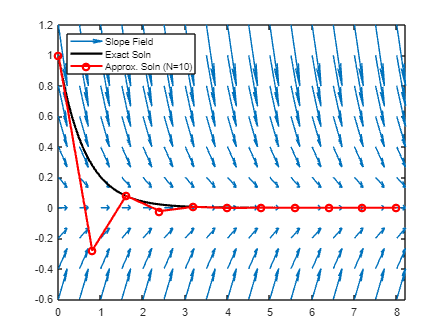

plot(t_approximate, y_approximate, 'ro-', 'linewidth', 2)
legend('Slope Field', 'Exact Soln', 'Approx. Soln (N=10)', 'location', 'northwest')
hold off;   %end plotting in this figure window

**Your essay answer goes here.**

This result is much more accurate for our ODE since we doubled our number of steps over the same interval, which means that Euler's method can estimate and redirect twice as much, which leads us to a much more accurate solution. This time we had to zoom in much tighter on our y-axis to see the inaccuracies at each estimation, which provides a good perspective on how much more accurate it is with only double the number of steps. 

# Exercise 3

**Read the instructions in your lab pdf file carefully!**

Display contents of impeuler M-file.

type 'impeuler.m'

function [t,y] = impeuler(f,tspan,y0,N)

% Solves the IVP y' = f(t,y), y(t0) = y0 in the time interval tspan = [t0,tf]
% using Euler's method with N time steps.
%  Input:
%  f = name of inline function or function M-file that evaluates the ODE
%          (if not an inline function,  use: euler(@f,tspan,y0,N))
%          For a system, the f must be given as column vector.
%  tspan = [t0, tf] where t0 = initial time value and tf = final time value
%  y0  = initial value of the dependent variable. If solving a system,
%           initial conditions must be given as a vector.
%  N   = number of steps used.
% Output:
%  t = vector of time values where the solution was computed
%  y = vector of computed solution values.

m = length(y0);
t0 = tspan(1);
tf = tspan(2);
h = (tf-t0)/N;             % evaluate the time step size
t = linspace(t0,tf,N+1);    % create the vector of t values
y = zeros(m,N+1);   % allocate memory for the output y
y(:,1) = y0';              % set initial condition
for n=

Define ODE function. 

f = @(t,y) y;

Compute numerical solution to IVP with Nsmall timesteps using "improved Euler."

[ t9 , y9 ] = impeuler (f ,[0 ,1.8] ,2 ,9); % use @ f if defined in separate m - file
[t9, y9]

ans =          0    2.0000
    0.2000    2.4400
    0.4000    2.9768
    0.6000    3.6317
    0.8000    4.4307
    1.0000    5.4054
    1.2000    6.5946
    1.4000    8.0454
    1.6000    9.8154
    1.8000   11.9748


*How does your output compare to that in the protocol? They should be the same.*

My output  is exactly the same as the output in the protocol.

# Exercise 4

**Read the instructions in your lab pdf file carefully!**

### **Part (a)**

Define ODE function $f$for your version of the lab.

f = @(t, y) y;

Define vector $t$ of time-values over the interval in your version of the lab, to compute analytical solution vector.

t = linspace(0, 1.8, 100); 
y = 2*exp(t);

Create vector of analytical solution values at corresponding t values.

solns = [t(1:100)', y(1:100)'];

Solve IVP numerically using improved Euler's method with Nsmall timesteps (use variable names as instructed).

[t9, y9]= impeuler(f, [0, 1.8], 2, Nsmall); % solve the ODE using Euler w / 9 steps
[t9, y9]

ans =          0    2.0000
    0.2000    2.4400
    0.4000    2.9768
    0.6000    3.6317
    0.8000    4.4307
    1.0000    5.4054
    1.2000    6.5946
    1.4000    8.0454
    1.6000    9.8154
    1.8000   11.9748


Solve IVP numerically using improved Euler's method with Nmed timesteps (use variable names as instructed).

[t90, y90]= impeuler(f, [0, 1.8], 2, Nmed); % solve the ODE using Euler w / 90 steps
[t90, y90]

ans =          0    2.0000
    0.0200    2.0404
    0.0400    2.0816
    0.0600    2.1237
    0.0800    2.1666
    0.1000    2.2103
    0.1200    2.2550
    0.1400    2.3005
    0.1600    2.3470
    0.1800    2.3944


Solve IVP numerically using improved Euler's method with Nlarge timesteps (use variable names as instructed).

[t900, y900]= impeuler(f, [0, 1.8], 2, Nlarge); % solve the ODE using Euler w / 900 steps
[t900, y900]

ans =          0    2.0000
    0.0020    2.0040
    0.0040    2.0080
    0.0060    2.0120
    0.0080    2.0161
    0.0100    2.0201
    0.0120    2.0241
    0.0140    2.0282
    0.0160    2.0323
    0.0180    2.0363


Solve IVP numerically using improved Euler's method with Nhuge timesteps (use variable names as instructed).

[t9000, y9000]= impeuler(f, [0, 1.8], 2, Nhuge); % solve the ODE using Euler w / 9000 steps
[t9000, y9000]

ans =          0    2.0000
    0.0002    2.0004
    0.0004    2.0008
    0.0006    2.0012
    0.0008    2.0016
    0.0010    2.0020
    0.0012    2.0024
    0.0014    2.0028
    0.0016    2.0032
    0.0018    2.0036


In the following steps, we define error as exact - numerical solution value at the last time step

Compute numerical solution error at the last time step for improved Euler with Nsmall timesteps (use variable names as instructed).

eNsmall = y(end)-y9(end)

eNsmall = 0.1245

Compute numerical solution error at the last time step for improved Euler with Nmed timesteps (use variable names as instructed).

eNmed = y(end)-y90(end)

eNmed = 0.0014

Compute numerical solution error at the last time step for improved Euler with Nlarge timesteps (use variable names as instructed).

eNlarge = y(end)-y900(end)

eNlarge = 1.4497e-05

Compute numerical solution error at the last time step for improved Euler with Nhuge timesteps (use variable names as instructed).

eNhuge = y(end)-y9000(end)

eNhuge = 1.4517e-07

Compute ratio of errors between N=Nsmall and N=Nmed. 

ratio1 = eNsmall/eNmed

ratio1 = 87.0417

Compute ratio of errors between N=Nmed and N=Nlarge.

ratio2 = eNmed/eNlarge

ratio2 = 98.6541

Compute ratio of errors between N=Nlarge and N=Nhuge. 

ratio3 = eNlarge/eNhuge

ratio3 = 99.8651

### **FILL OUT THE TABLE BELOW **

Display the table of errors and ratios of consecutive errors for the  numerical solution at `t=tfina`l (the last element in the solution vector).  **REPLACE** words "Nsmall", "Nmed", "Nlarge" and "Nhuge","Nsmall", "yNmed", "yNlarge" and "yNhuge" , "eNsmall",..."ratio1", ... by the appropriate numbers of steps you were given in your version of the lab and by the appropriate values you computed above.  

N ={Nsmall; Nmed; Nlarge; Nhuge};
Approximation={y9(end); y90(end); y900(end); y9000(end)};
Error={eNsmall; eNmed; eNlarge; eNhuge};
Ratio ={'N/A'; ratio1; ratio2; ratio3};
table(N,Approximation,Error,Ratio)

ans = 4×4 table
       N        Approximation        Error            Ratio   
    ________    _____________    ______________    ___________

    {[   9]}     {[11.9748]}     {[    0.1245]}    {'N/A'    }
    {[  90]}     {[12.0979]}     {[    0.0014]}    {[87.0417]}
    {[ 900]}     {[12.0993]}     {[1.4497e-05]}    {[98.6541]}
    {[9000]}     {[12.0993]}     {[1.4517e-07]}    {[99.8651]}


### **Part (b)**

The continous error rate in the improved Euler's method relates to the number of steps used as the error decreases by a factor of ~100 each time the steps are increased by a factor of 10. this means that, for every extra step the Ulers method equation uses, the error between the analytical answer and the Euler's approximation gets smaller by a factor of k^2=k, in other words, the error is reduced by a factor of k^2.

# Exercise 5

**Read the instructions in your lab pdf file carefully!** 

### Part (a)

Plot slopefield for the new ODE  using the given commands. 

clear;
t = 0:0.5:8; y = -11:1.8:7; % define a grid in t & y directions
[T, Y] = meshgrid(t, y); % create 2 d matrices of points in ty - plane
dT = ones(size(T)); % dt =1 for all points
dY = -1.6*Y; % dy = -1.6* y ; this is the ODE
quiver (T, Y, dT, dY) % draw arrows (t , y ) - >( t + dt , t + dy )
axis tight % adjust look
hold on

### Part (b)

Define vector t of time-values over the  given interval  to define analytical solution vector.

t_exact = linspace(0,8,100);

Create vector of analytical solution values at corresponding t values.

y_exact = exp(-1.6*t_exact);

Plot analytical solution vector with slopefield from (a). 

plot(t_exact, y_exact, 'k', 'linewidth', 2)

### Part (c)

Define ODE function.

funcODE = @(t, y) -1.6*y;

Compute numerical solution to IVP with N timesteps using improved Euler.

N=5;
[t_approximate, y_approximate] = impeuler(funcODE, [0,8], 1, N);
[t_approximate, y_approximate]

ans =          0    1.0000
    1.6000    1.7168
    3.2000    2.9474
    4.8000    5.0601
    6.4000    8.6872
    8.0000   14.9142


Plot numerical solution with analytical solution from (b) and slopefield from (a) using circles to distinguish between the approximated data (i.e., the numerical solution values) and actual (analytical) solution.

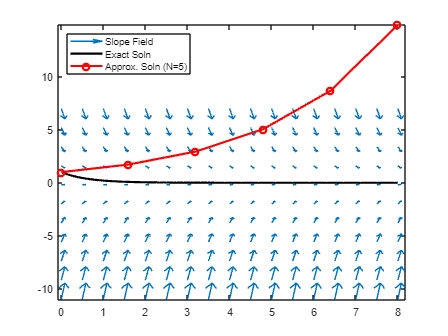

plot(t_approximate, y_approximate, 'ro-', 'linewidth', 2)
legend('Slope Field', 'Exact Soln', 'Approx. Soln (N=5)', 'location', 'northwest')
hold off;   %end plotting in this figure window

** Your response to the essay question for part (c) goes here. **

The geometric interpretation of Eulers method is based on the use of tangent lines that are used to approximate the solution to the ODE. Euler's approximations overestimate this particular solution because, while the shape of the graph that we are analyzing is concave up, similar to the regular ulers method, the approximations are getting worse and worse due to Uler's overcorrrecting. The imporved Euler's method shows a smoother trend than the regular Euler's method, but it tracks the real solution less accurately. The improved Uler's method uses a slope average which negates the underestimation because the use of two very incorrect estimations throws off the calculations entirely. This is still due to the very small amount of steps over the interval that we are analyzing.

### Part (d)

 Define new grid of t and y values at which to plot vectors for slope field.

figure
t = 0:0.5:8; y = -0.6:0.2:1.3;

Plot slope field  corresponding to the new grid.

[T, Y] = meshgrid(t, y); % create 2 d matrices of points in ty - plane
dT = ones(size(T)); % dt =1 for all points
dY = -1.6*Y; % dy = -1.6* y ; this is the ODE
quiver (T, Y, dT, dY) % draw arrows (t , y ) - >( t + dt , t + dy )
axis tight % adjust look
hold on;

Define vector t of time-values over the given interval to define analytical soution vector.

t_exact = linspace(0,8,100);

Create vector of analytical solution values at corresponding t values.

y_exact = exp(-1.6*t_exact);

Plot analytical solution vector with new slopefield.

plot(t_exact, y_exact, 'k', 'linewidth', 2)

Define ODE function.

funcODE = @(t, y) -1.6*y;

Compute numerical solution to IVP with the given timesteps using improved Euler. 

N=10;
[t_approximate, y_approximate] = impeuler(funcODE, [0,8], 1, N);

Plot numerical solution together with slope field and analytical solution

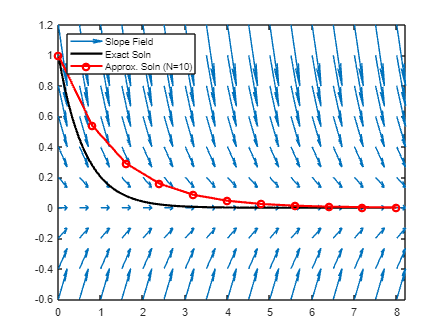

plot(t_approximate, y_approximate, 'ro-', 'linewidth', 2)
legend('Slope Field', 'Exact Soln', 'Approx. Soln (N=10)', 'location', 'northwest')
hold off;   %end plotting in this figure window

**The comparison between these approximations and the ones obtained using the reguler Uler's method brings to light that, while the improved ulers method might give us smoother approximation curves due to the use of the slope average, it does not provide us with a useful approximation unless the number of steps is a relativley large number. This number depends a lot on the interval and the specific equation, however this lab showed that the step size needs to be <1 at a very minimum. Even at the number of steps N=10 in this example, both Uler's and improved Uler's need to have a step size less than 0.8 to provide any sort of dependably accurate solution.**